%% One-Agent Spring–Damper MPC Example
clear; clc;

%% (Optional) Add required paths for YALMIP and any solvers
if false
    originalPath = 'M:\DMPC proj\matlab';
    addpath(genpath('M:\DMPC proj\matlab\YALMIP-master'));
    optiPath = 'M:\DMPC proj\matlab\OPTI-master'; 
    cd(optiPath);
    


    run('opti_Install.m');
    cd(originalPath);
end

%% Define physical parameters for the spring–damper system
m = 1;          % Mass (kg)
k = 1;          % Spring constant (N/m)
c = 0.1;        % Damping coefficient (N/(m/s))

%% Time horizon for the MPC optimization
t0 = 0;
T = 2;          % Length of the horizon (seconds)
N = 6;         % Number of discretization steps (dt = T/(N-1))
dt = T/(N-1);

%% Simulation parameters
T_sim = 5;     % Total simulation time (seconds)
dt_sample = dt;  % Sampling time (seconds)

%% Create Agent Data and the Single Agent
id = 1;
n_x = 2;        % State: [position; velocity]
n_u = 1;        % Control: force input

% Initial and reference states:
x0 = [0; 0];      % Start at rest at the origin
x_ref = [1; 0];   % Desired position 1 (with zero velocity)

% State and control bounds:
x_min = [-10; -10]; 
x_max = [10; 10];
u_min = -5; 
u_max = 5;

rho_init = 10;    % Penalty parameter initialization

% Create the Agent_data object
agentData = Agent_data(id, n_x, n_u, t0, T, N, x0, x_ref, x_min, x_max, u_min, u_max, rho_init);

%% Define cost weights (quadratic cost functions)
Q   = diag([1, 1]);       % Stage state weighting
R   = 0.1;                % Stage control weighting
Qf  = diag([10, 10]);     % Terminal state weighting

%% Define the dynamics for the spring–damper system
% The continuous dynamics are:
%   x1_dot = x2
%   x2_dot = (-k*x1 - c*x2)/m + (1/m)*u
% Here, u represents an extra control force.
f_i = @(x,u) [ x(2); (-k*x(1) - c*x(2))/m + u/m ];

%% Define cost functions
% Stage cost: penalizes deviation from the reference and control effort.
l_i = @(x,u,x_ref) (x - x_ref)'*Q*(x - x_ref) + u'*R*u;
% Terminal cost: penalizes final state error.
V_i = @(x,x_ref) (x - x_ref)'*Qf*(x - x_ref);

%% No additional constraints (dummy functions)
g_i = @(x,u) 0;
h_i = @(x,u) 0;
g_i_N = @(x,u) 0;
h_i_N = @(x,u) 0;

%% Create the single Agent object
% Note: We wrap the cost functions to "capture" the reference state.
agent = Agent(id, f_i, @(x) V_i(x, x_ref), @(x,u,t) l_i(x, u, x_ref), g_i, h_i, g_i_N, h_i_N, agentData);

% Since this is a single-agent problem, register an empty list of neighbors.
agent.register_neighbors({});

%% Create a solution container for the agent
solution = Solution(agent, dt_sample);

%% Create the ADMM Solver (with a single agent)
agents = {agent};
max_iterations = 50;
convergence_tolerance = 1e-3;
solver = ADMM_Solver(agents, {solution}, max_iterations, convergence_tolerance);

%% Run the MPC simulation loop
for t = 0:dt_sample:T_sim
    solver.solve();
    solver.shift(dt_sample);
end

Total number of variables............................:       15
                     variables with only lower bounds:        0
                variables with lower and upper bounds:       15
                     variables with only upper bounds:        0
Total number of equality constraints.................:       10
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0


Number of Iterations....: 6

                                   (scaled)                 (unscaled)
Objective...............:   6.9596160757686008e+00    6.9596160757686008e+00
Dual infeasibility......:   1.1029116479826942e-15    1.1029116479826942e-15
Constraint violation....:   5.5511151231257827e-17    5.5511151231257827e-17
Complementarity.........:   9.0909115591551582e-09    9.0909115591551582e-09
Overall NLP er

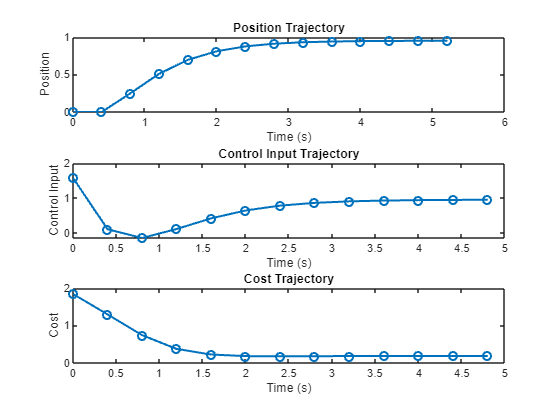

%% (Optional) Plot the results
figure;
subplot(3,1,1);
plot(solution.t, solution.x(1, :), '-o','LineWidth',1.5);
xlabel('Time (s)');
ylabel('Position');
title('Position Trajectory');

subplot(3,1,2);
plot(solution.t(:, 1:end-1), solution.u, '-o','LineWidth',1.5);
xlabel('Time (s)');
ylabel('Control Input');
title('Control Input Trajectory');

subplot(3,1,3);
plot(solution.t(:, 1:end-1), solution.cost, '-o','LineWidth',1.5);
xlabel('Time (s)');
ylabel('Cost');
title('Cost Trajectory');